Henting av data fra ADC, som lagres i 3 array M1, M2 og M3.

clear mypi;
mypi=raspi("192.168.43.6","Kollis","646djohr");

%Sample fra ADC-ene og lagre i en fil som overføres til denne mappen, og
%deretter slette filen fra pi-en
system(mypi,'lab1/./adc_sampler 31250 /home/Kollis/lab1/datafiler/SAMPLE.bin','sudo');
getFile(mypi,'/home/Kollis/lab1/datafiler/SAMPLE.bin','C:\Users\skaug\OneDrive\Skole\2024-06-VÅR\TTT4280 - Sensorer og instrumentering\Lab\Lab2 - Akustikk\Data');
deleteFile(mypi,'/home/Kollis/lab1/datafiler/SAMPLE.bin');

channels=5;
nBits=12;
V_ref=3.3;
d=0.06 %distanse mellom mikrofoner 30cm 

d = 0.0600

c=343 %Lydhastighet

c = 343


fid=fopen("SAMPLE.bin","rb");

nomPeriod=fread(fid,1,"double");
data=fread(fid,"uint16");

nSamples=numel(data)/channels; %Antall sampler per ADC
dataMatrix = reshape(data,channels,nSamples); %Matrise med verdiene til ADC-ene i hver rad
fclose(fid);

M1 = dataMatrix(1,:)*V_ref./(2^nBits); %Mikrofon #1
M2 = dataMatrix(2,:)*V_ref./(2^nBits); %Mikrofon #2
M3 = dataMatrix(3,:)*V_ref./(2^nBits); %Mikrofon #3

M1=M1-mean(M1);
M2=M2-mean(M2);
M3=M3-mean(M3);
nomPeriod=nomPeriod * 1e-6;
n=1:nSamples;
t=n*nomPeriod;

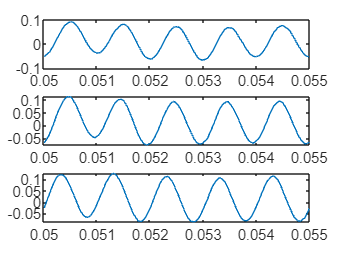

figure;
subplot(3,1,1);
plot(t,M1);
xlim([0.05 0.055]);
subplot(3,1,2);
plot(t,M2);
xlim([0.05 0.055]);
subplot(3,1,3);
plot(t,M3);
xlim([0.05 0.055]);

fs=1/nomPeriod;
nUpsample=15;
fc=1/(2*nUpsample);

M1Up=upsample(M1,nUpsample);
M2Up=upsample(M2,nUpsample);
M3Up=upsample(M3,nUpsample);

M1Up=lowpass(M1Up,fc,fs);
M2Up=lowpass(M2Up,fc,fs);
M3Up=lowpass(M3Up,fc,fs);

maxLag= ceil(nUpsample*fs*d/c); % i sampler
n=1:nSamples*nUpsample;

[r11,~]=xcorr(M1Up,M1Up,maxLag);
[r22,~]=xcorr(M2Up,M2Up,maxLag);
[r33,~]=xcorr(M3Up,M3Up,maxLag);

[r21,~]=xcorr(M2Up,M1Up,maxLag); %Autokorrelasjon mellom mikrofoner maxLag=100
[r31,~]=xcorr(M3Up,M1Up,maxLag);
[r32,l]=xcorr(M3Up,M2Up,maxLag);

[y21,n21]=max(r21);
n21=n21-(length(r21)+1)/2; %Lag/delay mellom M1 og M2 i antall sampler

[y31,n31]=max(r31);
n31=n31-(length(r31)+1)/2; 

[y32,n32]=max(r32);
n32=n32-(length(r32)+1)/2;

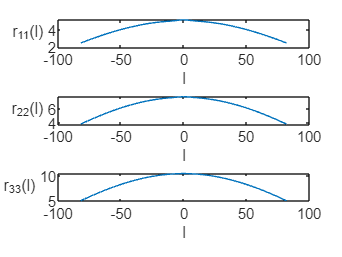

figure;
subplot(3,1,1);
plot(l,r11);
ylabel("r_{11}(l)");
xlabel("l");
set(get(gca,'ylabel'),'rotation',0);
subplot(3,1,2);
plot(l,r22);
ylabel("r_{22}(l)");
xlabel("l");
set(get(gca,'ylabel'),'rotation',0);
subplot(3,1,3);
plot(l,r33);
ylabel("r_{33}(l)");
xlabel("l");
set(get(gca,'ylabel'),'rotation',0);

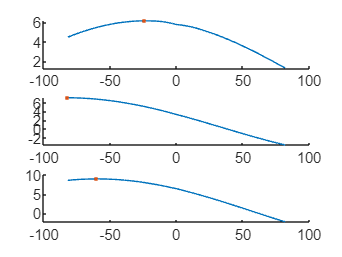

figure;
subplot(3,1,1);
hold on;
plot(l,r21);
plot(n21,y21,'.');
subplot(3,1,2);
hold on;
plot(l,r31);
plot(n31,y31,'.');
subplot(3,1,3);
hold on;
plot(l,r32);
plot(n32,y32,'.');

theta=-rad2deg(atan2(sqrt(3)*(n21+n31),(n21-n31-2*n32)));
disp(theta);

   45.8868

